# Демодуляция. Часть 1.

# Double Sideband Transmitted Carrier 

# (AM-DSB-TC)

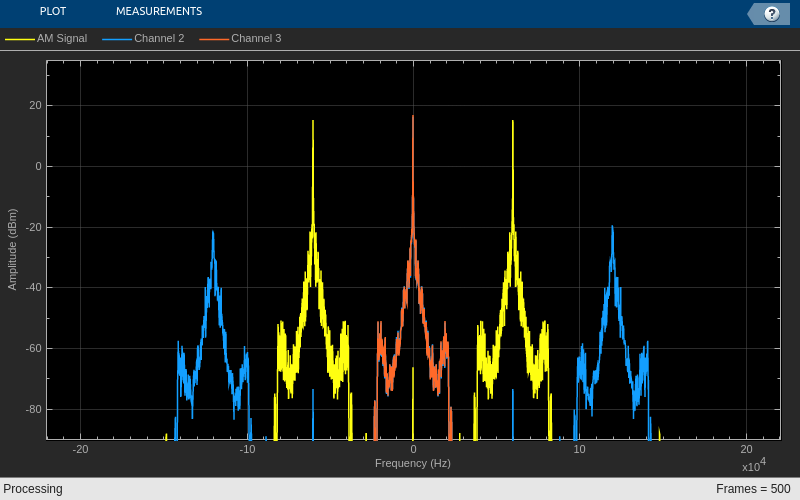

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

FreqOffset = 0;             % расстройка по частоте (Hz)
PhaseOffset = 0 * pi/180;   % расстройка по фазе (градусы)

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения
AudioFrameSize = SignalFrameSize / RateRatio;   % количество отсчетов аудиосообщения, получаемых за один раз

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', Fc + FreqOffset,...
    'PhaseOffset', pi/2 + PhaseOffset...
    );

% рассчет коэффициентов фильтра нижних частот
cd matlab/DSB_TC;
H = Audio_Lowpass_FIR_Coeff();
cd ../..;

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* Carrier();

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal MixedSignal BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end


% проигрывание полученного сообщения
sound(Message, AudioFs);
